# Workspace & Robot Plotting - Example (made-up dimensions)

clc; clear; close all;

## Data

L = [2 1.1 3 1 1.5];
angle = pi/6;
limits = [-pi pi 0 3 -0.5*pi 0.5*pi];

## Old Version

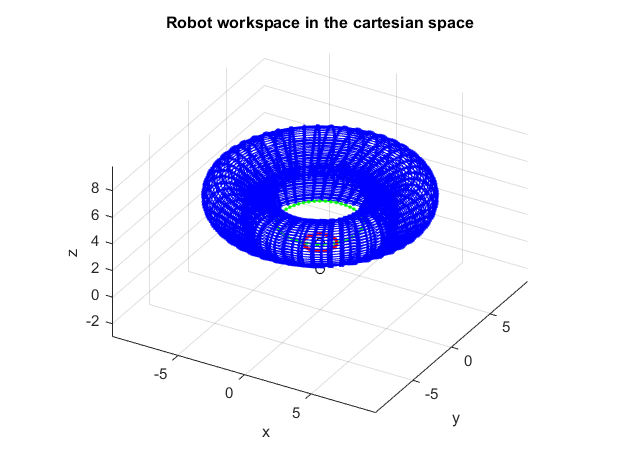

figure
plot_workspace_OLD(L,angle,limits,gcf)

## Current Version

### Workspace

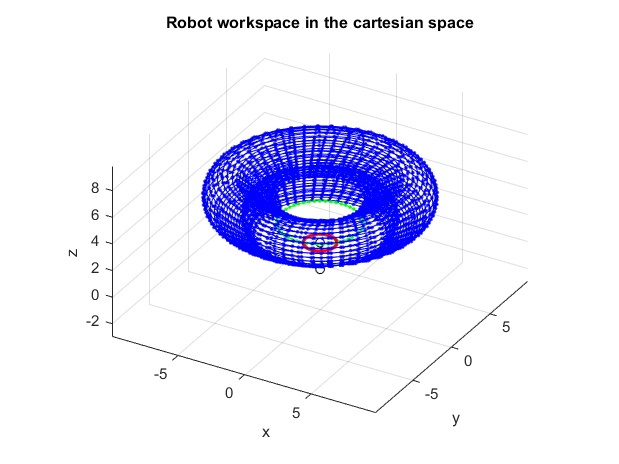

nPoints = [50 15 15];
volume_Flag = 'off';

figure
plot_workspace(L,angle,limits,gcf,nPoints,volume_Flag)

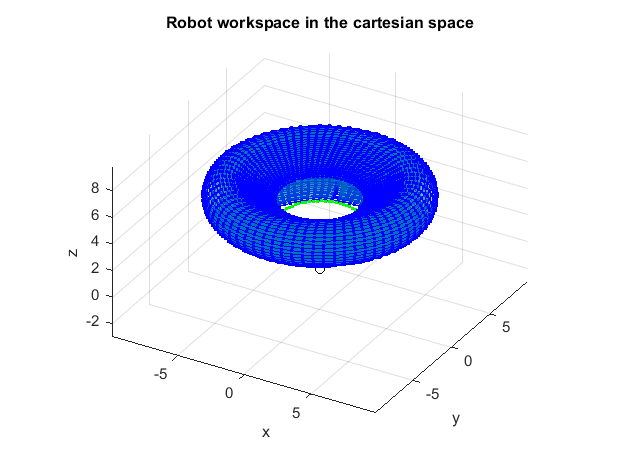

nPoints = [70 20 20];
volume_Flag = 'on';

figure
plot_workspace(L,angle,limits,gcf,nPoints,volume_Flag)

### Manipulator

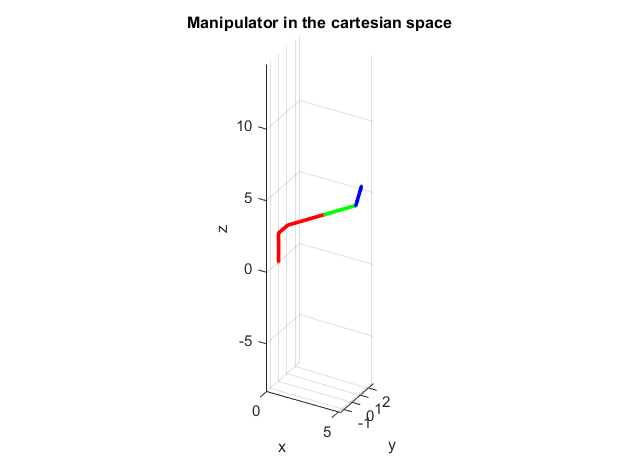

Q = {0.5*pi; 1.5; 0.25*pi};

figure
plot_robot(Q,L,angle,gcf)
grid on
axis equal
view(30,30)
xlabel('x'); ylabel('y'); zlabel('z')
title('Manipulator in the cartesian space')

## Check Inverse Kinematics

Q = {0.5*pi; 1.5; -0.15*pi};
[S,~] = dir_kin(Q,L,angle);

sol = 1;
Q_inv_kin = inv_kin(S,L,angle,sol);

Q0 = {0.4*pi; 1.2; 0.15*pi};
Q_inv_kin_numerical = inv_kin_numerical(S,L,angle,Q0);


Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<stopping criteria details>


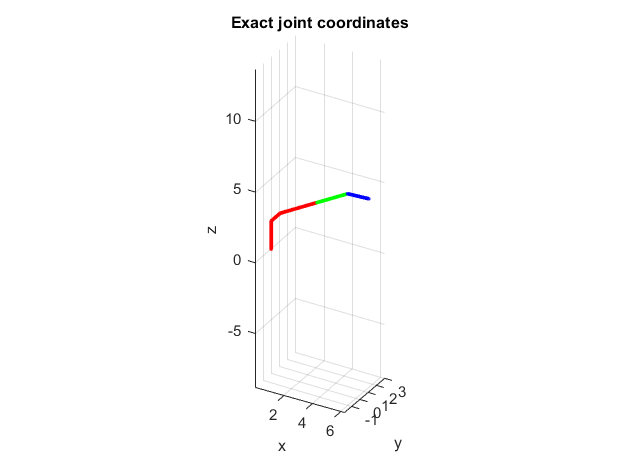

figure
plot_robot(Q,L,angle,gcf)
grid on
axis equal
view(30,30)
xlabel('x'); ylabel('y'); zlabel('z')
title('Exact joint coordinates')

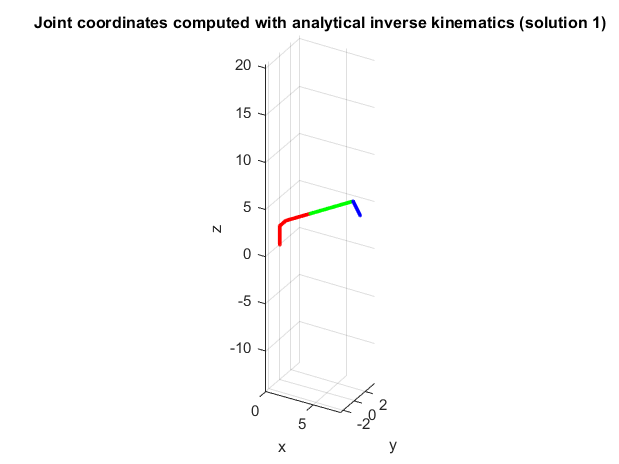

figure
plot_robot(Q_inv_kin,L,angle,gcf)
grid on
axis equal
view(30,30)
xlabel('x'); ylabel('y'); zlabel('z')
title('Joint coordinates computed with analytical inverse kinematics (solution 1)')

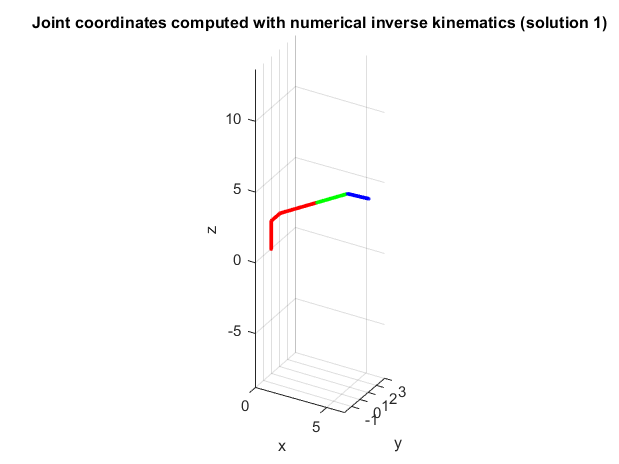

figure
plot_robot(Q_inv_kin_numerical,L,angle,gcf)
grid on
axis equal
view(30,30)
xlabel('x'); ylabel('y'); zlabel('z')
title('Joint coordinates computed with numerical inverse kinematics (solution 1)')